clc; clear; close all; addpath z_toolbox; 
load("E:\IEDpropagation\step5_IEDxcorr_polyfit\IED6d0_XC100ms_polyfit_delay_fibN_as.mat");
x = fibNas; y = IEDxcDas;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4300

     0



figure('Units', 'centimeters', 'Position', [5, 5, 26, 20]);
subplot(2, 2, 1);
f_densityScatter(x, y, 1);
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x = fibNres; y = IEDxcDres;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.0778

   2.1238e-38



subplot(2, 2, 2);
f_densityScatter(x, y, 1);
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('IED-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load("E:\IEDpropagation\step6_NAxcorr_polyfit\NAnon6d0IED_XC100ms_polyfit_delay_fibN_as.mat")
x = fibNas; y = NAxcDas;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4391

     0



subplot(2, 2, 3);
f_densityScatter(x, y, 1);
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x = fibNres; y = NAxcDres;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.0861

   1.0868e-46



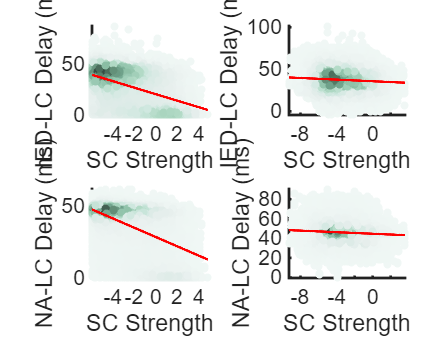

subplot(2, 2, 4);
f_densityScatter(x, y, 1);
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('SC Strength'); 
ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);